# Euler Bernoulli beam with cubic spring and damper

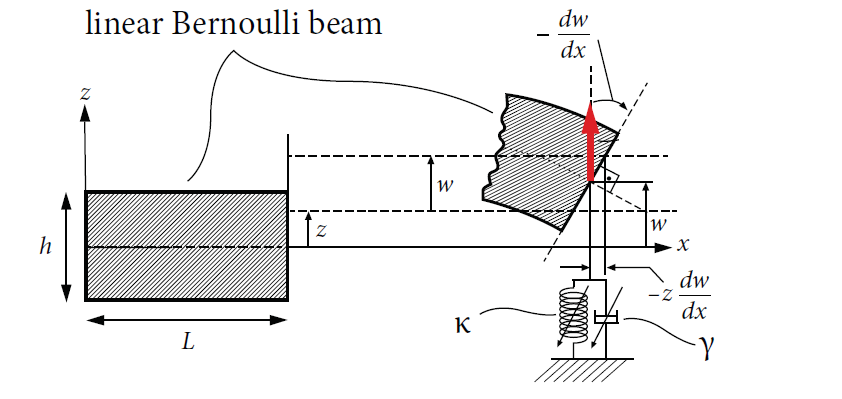

Additionally to external excitation on the last node parametric excitation is applied as well. The tip of the beam is subject to linear parametric excitation. The experiment this example is based on can be found in 

Chen, C. C. & Yeh, M. K.:  *Parametric instability of a beam under electromagnetic excitation*. Journal of Sound and Vibration 240,747–764, [https://doi.org/10.1006/jsvi.2000.3255](https://doi.org/10.1006/jsvi.2000.3255) 

## Generate model

clear all
nElements = 5;
kappa = 50; % cubic spring
gamma = 0.01; % cubic damping
mu = 45;
[M,C,K,fnl,fext] = build_model_external(kappa, gamma, nElements,mu);

n = length(M);

## Dynamical system setup 

We consider the parametrically excited system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{g}(\mathbf{x},\dot{\mathbf{x}},\Omega t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{G}(\mathbf{z},\phi),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where


$$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{G}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{g}(\mathbf{x, \dot{x}},\phi)\\
\mathbf{0}
\end{array}\right]$$


DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')

epsilon = 0.002;;
DS.add_forcing(fext,epsilon);

## Linear Modal Analysis 

% Analyse spectrum
[V,D,W_evec] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 8.840017e-04
modal damping ratio for 2 mode is 5.488086e-03
modal damping ratio for 3 mode is 1.541080e-02
modal damping ratio for 4 mode is 3.044305e-02
modal damping ratio for 5 mode is 5.052761e-02

 The first 10 eigenvalues are given as 
   1.0e+02 *

  -0.0001 + 0.0700i
  -0.0001 - 0.0700i
  -0.0024 + 0.4389i
  -0.0024 - 0.4389i
  -0.0190 + 1.2327i
  -0.0190 - 1.2327i
  -0.0741 + 2.4343i
  -0.0741 - 2.4343i
  -0.2042 + 4.0370i
  -0.2042 - 4.0370i



#### Choose Master subspace (perform resonance analysis)

% Set up SSM object
S = SSM(DS);
set(S.Options, 'reltol', 0.3,'notation','multiindex')

%Choose Master subspace
resModes = [1,2];
S.choose_E(resModes);

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2409 +43.8926i
  -0.2409 +43.8926i
  -0.2409 +43.8926i
  -0.2409 -43.8926i
  -0.2409 -43.8926i
  -0.2409 -43.8926i

sigma_out = 3300
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0006i
  -0.0062 + 7.0006i
  -0.0062 + 7.0006i
  -0.0062 + 7.0006i
  -0.0062 - 7.0006i
  -0.0062 - 7.0006i
  -0.0062 - 7.0006i
  -0.0062 - 7.0006i

sigma_in = 3300


## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = 5; % SSM approximation order
outdof = [n-2 n-1]; % degree of freedom at which output is displayed


setup options


set(S.Options, 'reltol', 1,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'nt', 2^7, 'nRho', 200, 'nPar', 200, 'nPsi', 100, 'rhoScale', 2 )
set(S.FRCOptions, 'method','level set') 
set(S.FRCOptions, 'outdof',outdof)

choose frequency range

omega0 = imag(S.E.spectrum(1));
OmegaRange = omega0*[0.95 1.15];

Extract forced response curve

parSubRange =     6.6506    8.0507


*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     0
     7     1
     8     1
     8     2
     0     6
     0     7
     1     7
     1     8
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2409 +43.8926i
  -0.2409 +43.8926i
  -0.2409 +43.8926i
  -0.2409 +43.8926i
  -0.2409 +43.8926i
  -0.2409 -43.8926i
  -0.2409 -43.8926i
  -0.2409 -43.8926i
  -0.2409 -43.8926i
  -0.2409 -43.8926i

sigma_out = 3300
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0006i
  -0.0062 + 7.0006i
  -0.0062 + 7.0006i
  -0.0062 + 7.0006i
  -0.0062 - 7.0006i
  -0.0062 - 7.0006i
  -0.0062 

nPar = 201

ans = 'Manually inserting omega0 into par in FRC_level_set'

d = 0.0018

ix = 51

par =     6.6506    6.6576    6.6646    6.6717    6.6787    6.6857    6.6928    6.6998    6.7068    6.7139    6.7209    6.7280    6.7350    6.7420    6.7491    6.7561    6.7631    6.7702    6.7772    6.7842    6.7913    6.7983    6.8053    6.8124    6.8194    6.8265    6.8335    6.8405    6.8476    6.8546    6.8616    6.8687    6.8757    6.8827    6.8898    6.8968    6.9038    6.9109    6.9179    6.9250    6.9320    6.9390    6.9461    6.9531    6.9601    6.9672    6.9742    6.9812    6.9883    6.9953


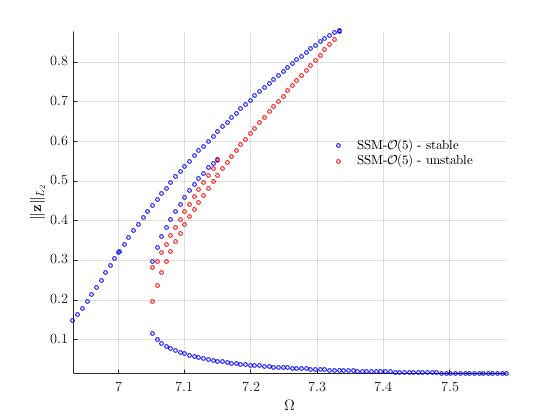

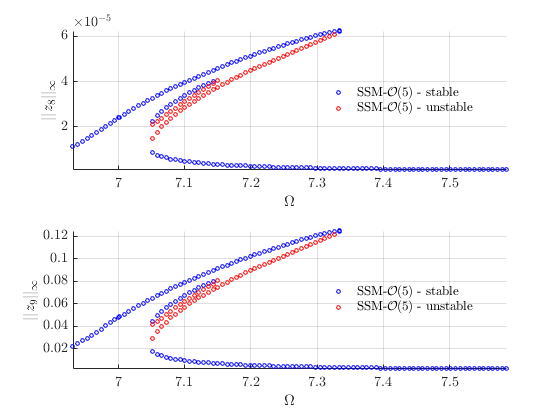

Total time spent on FRC computation upto O(5) = 00:01:12


startFRCSSM = tic;
FRC_SSM = S.extract_FRC('freq',OmegaRange,order);

timings.FRCSSM = toc(startFRCSSM)

timings = struct with fields:
    FRCSSM: 76.5974


## Verification: Collocation using [coco](https://sourceforge.net/p/cocotools/wiki/Home/)

Dankowicz, H., & Schilder, F. (2013).  *Recipes for Continuation,* SIAM Philadelphia. [<https://doi.org/10.1137/1.9781611972573](https://doi.org/10.1137/1.9781611972573)>


 Run='FRC0.002': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          4.78e-03  9.50e+00    0.0    0.0    0.0
   1   1  1.00e+00  1.88e-02  7.95e-07  9.50e+00    0.1    0.2    0.1
   2   1  1.00e+00  4.21e-06  3.55e-13  9.50e+00    0.1    0.4    0.1
   3   1  1.00e+00  2.33e-13  1.32e-13  9.50e+00    0.1    0.6    0.2

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp8         amp9
    0  00:00:03   9.5028e+00      1  EP      6.6506e+00   9.4476e-01   2.0000e-03   1.9201e-06   3.7842e-03
   10  00:00:44   9.8063e+00      2          6.8627e+00   9.1555e-01   2.0000e-03   5.3478e-06   1.0577e-02
   20  00:01:07   1.0851e+01      3          7.0895e+00   8.8626e-01   2.0000e-03   3.8253e-05   7.6031e-02
   30  00:01:34   1.2245e+01      4          7.2575e+00   8.6575e-01   2.0000e-03   

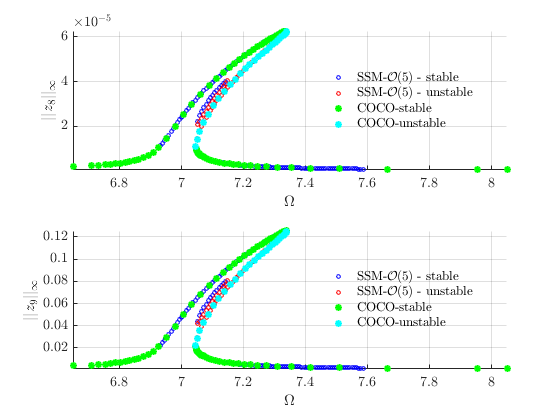

nCycles = 10;

coco = cocoWrapper(DS, nCycles, outdof);
set(coco,'initialGuess','linear')
set(coco.Options, 'NAdapt', 1);
set(coco.Options,'NTST', 20,'PtMX',200); 

startcoco = tic;
bd = coco.extract_FRC(OmegaRange);

timings.cocoFRC = toc(startcoco)

timings = struct with fields:
     FRCSSM: 76.5974
    cocoFRC: 290.3649


## Verification of Isola

Using contiunation of an initial periodic orbit, the isola detected by SSMtheory can be verified with coco.


 Run='FRC0.002': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          4.52e-06  1.19e+01    0.0    0.0    0.0
   1   1  1.00e+00  3.38e-03  2.11e-08  1.19e+01    0.0    1.5    0.2
   2   1  1.00e+00  8.63e-06  1.62e-12  1.19e+01    0.0    2.6    0.4
   3   1  1.00e+00  6.40e-11  8.69e-13  1.19e+01    0.0    3.5    0.7

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp8         amp9
    0  00:00:06   1.1872e+01      1  EP      7.0556e+00   8.9053e-01   2.0000e-03   2.3854e-05   4.7361e-02
    1  00:00:12   1.1939e+01      2  EP      7.0556e+00   8.9053e-01   2.0000e-03   2.3854e-05   4.7360e-02

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          9.00e-13  1.19e+01   

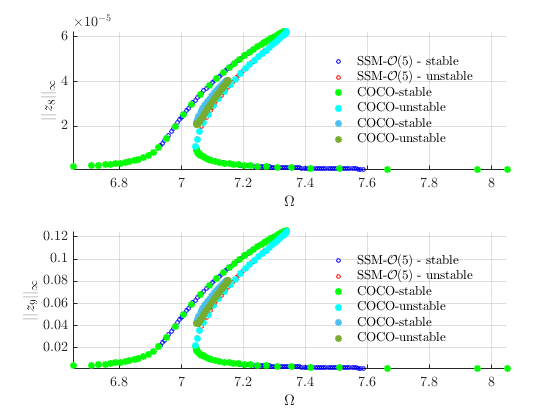

bd_isola = 1×1 cell array
    {193×29 cell}


% Initial Condition on Isola obtained from SSM
load('FRC_IC.mat')

IC = FRC.Zic.';
OmegaIC = FRC.Omega;

nCycles = 10;

coco = cocoWrapper(DS, nCycles, outdof);
set(coco,'initialGuess','linear')
set(coco.Options, 'NAdapt', 1);
set(coco.Options,'NTST', 80,'PtMX',90,'bi_direct',false); 

% Extract Isola
startcoco = tic;
bd_isola = coco.extract_FRC_fromIC(OmegaRange,IC,OmegaIC);

timings.cocoFRCisola = toc(startcoco)

timings = struct with fields:
          FRCSSM: 76.5974
         cocoFRC: 290.3649
    cocoFRCisola: 1.2701e+03


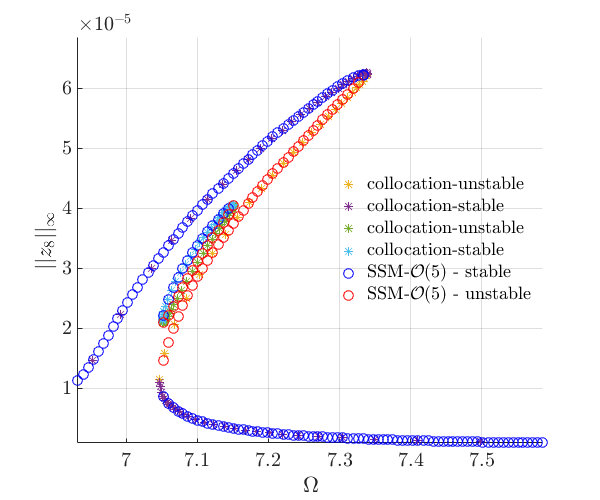

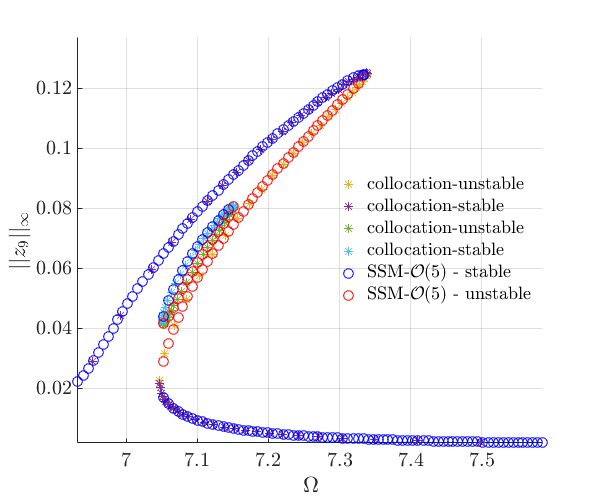

% Plot for paper
BBplotFRC(FRC_SSM,bd{1},order,outdof,bd_isola{1})